Uses all GLASS ozone profiles to produce simulated lidar signals

    ozone profiles with missing data are linearly interpolated where data is missing

Neural network is trained on ozone profiles and synthetic lidar signals

% clc; clearvars;

addpath(genpath("C:\Users\tely1\OneDrive\Desktop\EEJ9903\lidar_model\functions"));
addpath(genpath("C:\Users\tely1\OneDrive\Matlab Onedrive\O3_Lidar\proc_functions"));
addpath(genpath("C:\Users\tely1\OneDrive\Desktop\EEJ9903\ai\functions"));

dz = 30;
alt = 1e3:dz:5e3;

n_z = length(alt);

load("C:\Users\tely1\OneDrive\Desktop\EEJ9903\ai\dir\all_glass_profiles.mat");

n_glass_files = size(glass_dataset,1);
% n_o3_prof = 0;

o3_prof = NaN(n_z,0);

count = 1;
for i = 1:n_glass_files
    temp = glass_dataset(i,:);

    temp_glass_data = read_glass(temp.file);
    temp_no3 = temp_glass_data.N';
    temp_no3(temp_no3<0) = NaN;

    temp_alt = temp_glass_data.alt;

    % n_o3_filled = fillmissing(temp_no3,"linear",1,"EndValues","previous");

    for j = 1:size(temp_no3,2)
        o3_prof(:,end+1) = interp1(temp_alt,temp_no3(:,j),alt);
    end
end

o3_prof_fill = fillmissing(o3_prof,"linear",1,"EndValues","next");
o3_prof_fill = fillmissing(o3_prof_fill,"linear",1,"EndValues","previous");

% o3_prof_fill = o3_prof_fill(:,1:200);

% Ozone Absorption Cross Section
BDM = load("C:\Users\tely1\OneDrive\Desktop\EEJ9903\lidar_model\cross_sections\ozone\bdm\bdm_287_299.mat");

o3_287 = BDM.BDM_c287(1) .* 1e-4; % use first temp dependent cross section for now
o3_299 = BDM.BDM_c299(1) .* 1e-4;

do3 = BDM.BDM_d_287_299(1) .* 1e-4;

% Air Number Density
Nair = airNumberDensity(alt);

sigma_m_on = rayleigh_cross_section(287.2e-9);   
sigma_m_off = rayleigh_cross_section(299.1e-9);   
dsigma_m = sigma_m_on - sigma_m_off;

D_No3 = dsigma_m .* Nair ./ do3;

% Prepare parameters for signal calculation
E0_287 = 10.6e-3;
E0_299 = 6.3e-3;

eta_287 = 1/53.1572075; % Efficiency factor
eta_299 = 1/47.0176125; % 

etaQ = 0.7;

t_r = .2;   % Radius of the receiver in meters
o_r = 0.1;  % Radius of the obstruction
tau = 6e-9; % Laser pulse duration

alt_inst = 100;

id_bad = find(any(isnan(o3_prof_fill),1))

id_bad =          699         700        1083        1862        2418        2420        2437        2438        2666        2667


o3_prof_fill(:,id_bad) = [];

% Calculate the signal using the defined parameters
N_287 = signal(alt,alt_inst,287.2e-9,E0_287,t_r,o_r,tau,eta_287,etaQ,Nair,o3_287,o3_prof_fill); 
N_299 = signal(alt,alt_inst,299.1e-9,E0_299,t_r,o_r,tau,eta_299,etaQ,Nair,o3_299,o3_prof_fill); 

i_start = 1;
signals = NaN(length(alt)-i_start+1, 1, 2, size(N_287, 2));

for i = 1:size(N_287,2)
    signals(:,1,1,i) = N_287(i_start:end,i);
    signals(:,1,2,i) = N_299(i_start:end,i);
end

profiles = o3_prof_fill(i_start:end,:);

% n_prof = size(profiles,2);

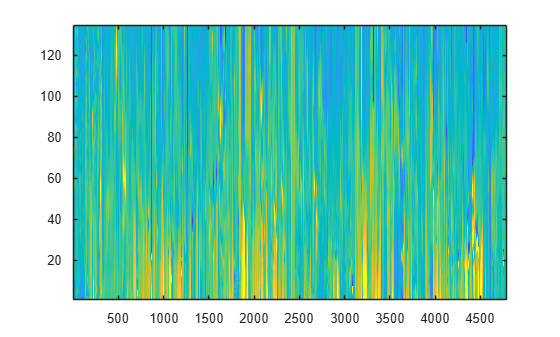

% find(any(o3_prof_fill<=0,1))
% find(any(isnan(signals),1))
% any(isinf(signals),1)
% any(signals<=0,1)
% signals(:,1,:,id_bad) = [];

figure;
imagesc(profiles)
set(gca, 'YDir','normal')
clim([0 2e18])

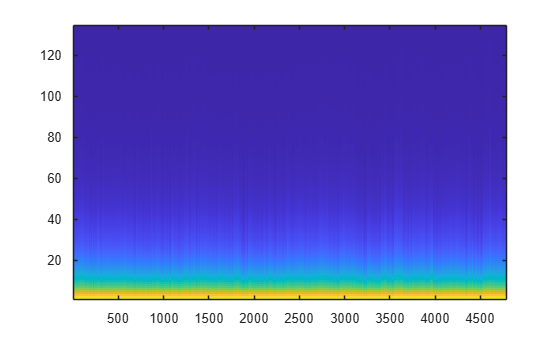

figure;
imagesc(squeeze(signals(:,:,1,:)))
set(gca, 'YDir','normal')

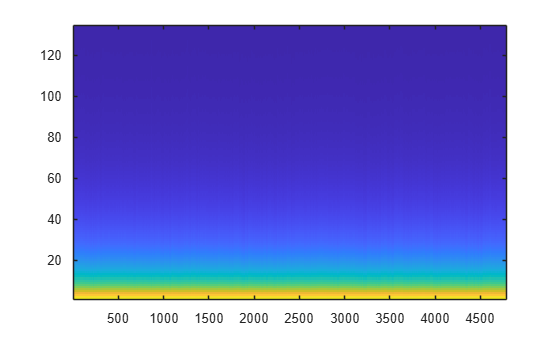

figure;
imagesc(squeeze(signals(:,:,2,:)))
set(gca, 'YDir','normal')

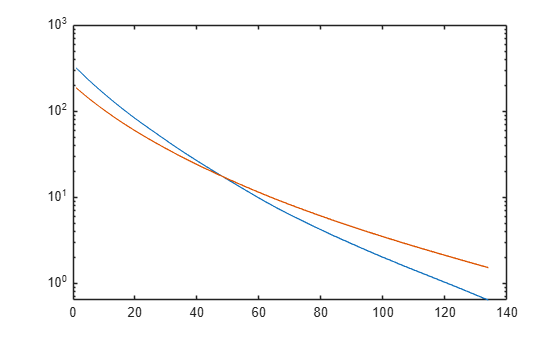

id = 7;
test_287 = signals(:,1,1,id);
test_299 = signals(:,1,2,id);

sig = log(test_299./test_287);
S = diff(sig)./dz;
N_sim = S./(2*do3)' - D_No3(i_start+1:end)';

figure;
semilogy(test_287,'DisplayName','287')
hold on
plot(test_299,'DisplayName','299')
hold off

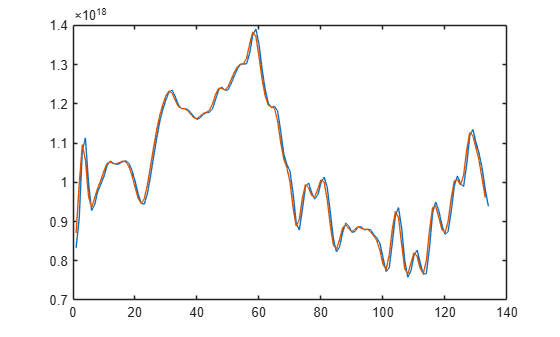

figure;
plot(profiles(:,id))
hold on
plot(N_sim)
hold off

n_prof = size(profiles,2);

[idx_train,idx_validation, idx_test] = trainingPartitions(n_prof,[.85, .1, .05]);

signals_train = signals(:,1,:,idx_train);
profiles_train = profiles(:,idx_train);

signals_validation = signals(:,:,:,idx_validation);
profiles_validation = profiles(:,idx_validation)';

signals_test = signals(:,:,:,idx_test);
profiles_test = profiles(:,idx_test)';

load("C:\Users\tely1\OneDrive\Desktop\EEJ9903\ai\dir\network.mat");

learn_rate = 0.01;
ephochs = 10;
patience = 50;

options = trainingOptions("sgdm", ...
    MaxEpochs=ephochs, ...
    Verbose=false, ...
    Plots="training-progress",...
    InitialLearnRate=learn_rate, NormalizeTargets=true, ValidationData={signals_validation, profiles_validation}, ValidationPatience=patience);

% options = trainingOptions("sgdm", ...
%     MaxEpochs=ephochs, ...
%     Verbose=false, ...
%     Plots="training-progress",...
%     InitialLearnRate=learn_rate, NormalizeTargets=true);

nettrained = trainnet(signals_train,profiles_train',net_1,"mse", options);

n_test = size(profiles_test,1);

v = 154;
X = signals_test(:,:,:,v);

s = predict(nettrained, X);

s_true = profiles_test(v,:);


figure('Position',[0, 0, 800, 600])
plot(s,alt./1000,'DisplayName','predicted')
hold on
plot(s_true,alt./1000,'DisplayName','true')
hold off
legend
grid on